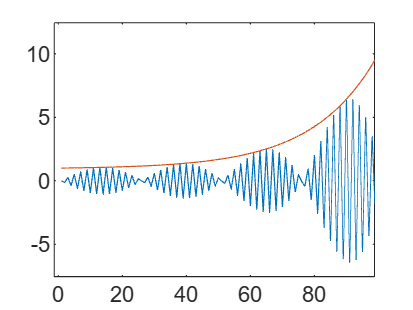

close all
clear
clc
x = linspace(0, 3 * pi, 100);
f = 100;
y = sin(2 * pi * f * x);
[A, B] = exponential_envelop(y, 1, 10);
plot(A)
hold on
plot(B)

function [output, envelop] = exponential_envelop(y, amp1, amp2)
    [row, col] = size(y); % row = 1, col = n
    [a, b] = exponentialFit(1, amp1, col, amp2);
    x = 1:1:col;
    envelop = a * func(x) + b;
    output = y .* envelop;
end

function [a, b] = exponentialFit(x1, y1, x2, y2)
    % 计算指数函数参数
    a = (y2 - y1) / (func(x2) - func(x1));
    b = y1 - a * func(x1);
end

function y = func(x)
    y = exp(0.05 * x);
end